## ***转置矩阵***

a=[1 2 3;4 5 6;7 8 9]

a =      1     2     3
     4     5     6
     7     8     9


a'

ans =      1     4     7
     2     5     8
     3     6     9


## ***计算函数表达式***

### **eval(f(x))**

**x为变量**

**计算当x=x0时，f的值**

例子：

syms x y z
y=x+2;
z=x^2+2;
x=3;
eval(y)

ans = 5

eval(z)

ans = 11

## **2D图的绘制**

#### **1.plot(x,y)**

**x为向量(eg:x=-5:0.1:5)**

#### **2. ezplot('x(t)','y(t)',[t1,t2])---绘制隐函数**

**x(t),y(t)为字符串**

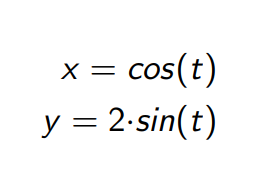

例子1：

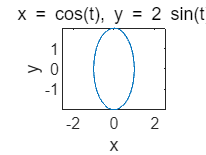

ezplot('cos(t)','2*sin(t)',[0,2*pi])

例子2：

**隐函数的2D绘制**

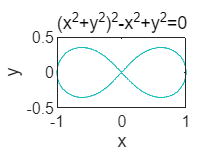

ezplot('(x^2+y^2)^2-x^2+y^2=0',[-1,1,-0.5,0.5])

### **极坐标函数的绘制**

#### **1. ezpolar('f(x)',[x1,x2])**

**f(x)为字符型**

例子：

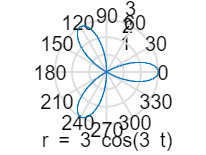

ezpolar('3*cos(3*t)',[0,2*pi])

#### **2.polar(x,y)**

**x为向量**

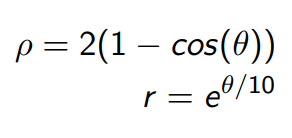

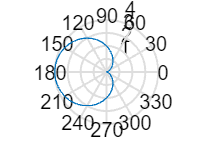

theta=0:0.1:2*pi;%以向量的形式
rho=2*(1-cos(theta));
polar(theta,rho)

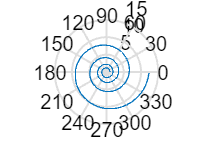

theta=0:0.1:8*pi;
rho=exp(0.1*theta);
polar(theta,rho)

### **分段函数的绘制**

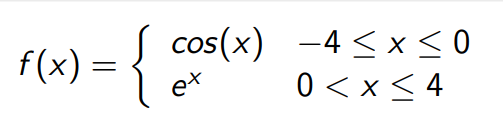

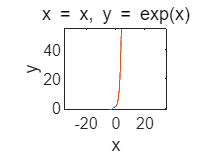

syms x;
ezplot('x','cos(x)',[-4,0])
hold on
ezplot('x','exp(x)',[0,4])

## **3D图的绘制**

#### **1.plot3(x(t),y(t),z(t))**

**t为向量**

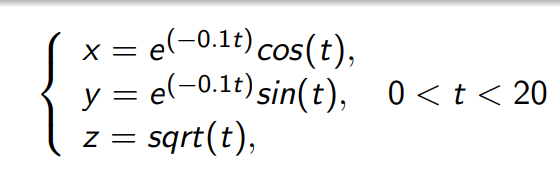

clear;
clf;%清除原图像
t=0:0.1:20;
r=exp(-0.1*t)

r =     1.0000    0.9900    0.9802    0.9704    0.9608    0.9512    0.9418    0.9324    0.9231    0.9139    0.9048    0.8958    0.8869    0.8781    0.8694    0.8607    0.8521    0.8437    0.8353    0.8270    0.8187    0.8106    0.8025    0.7945    0.7866    0.7788    0.7711    0.7634    0.7558    0.7483    0.7408    0.7334    0.7261    0.7189    0.7118    0.7047    0.6977    0.6907    0.6839    0.6771    0.6703    0.6637    0.6570    0.6505    0.6440    0.6376    0.6313    0.6250    0.6188    0.6126


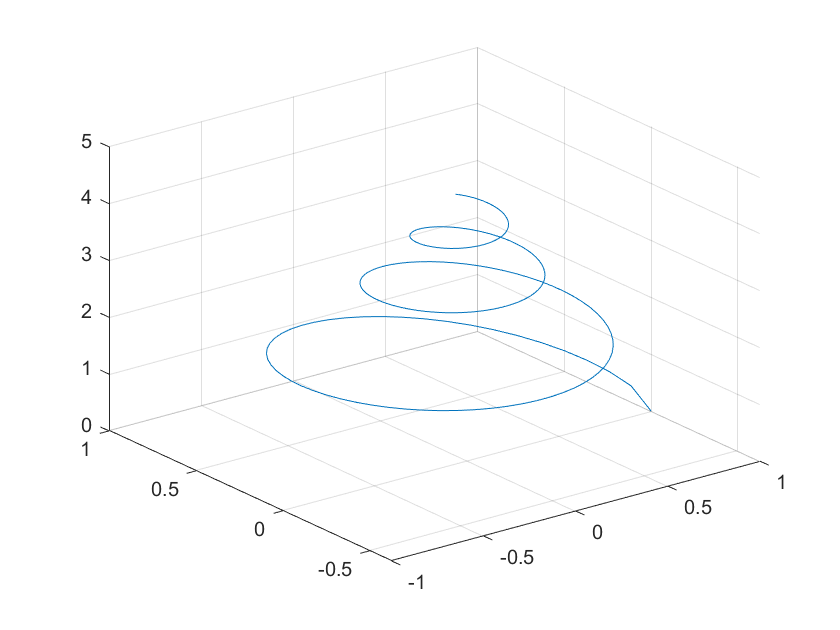

x =r.*cos(t);
y=r.*sin(t);
z=sqrt(t);
plot3(x,y,z);
grid on;%画格子

## 练习1

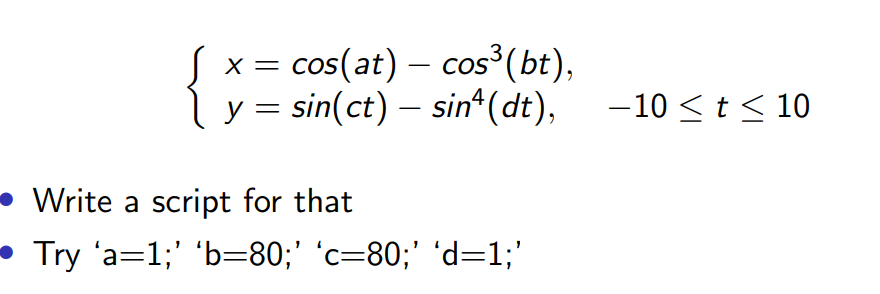

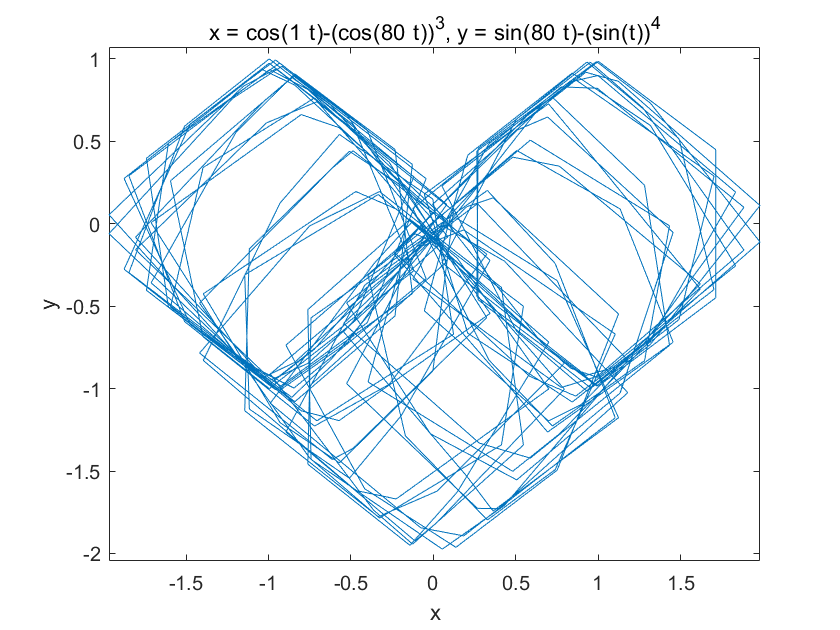

ezplot('cos(1*t)-(cos(80*t))^3','sin(80*t)-(sin(t))^4',[-10,10])

练习2

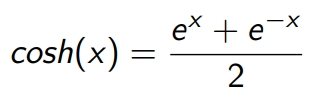

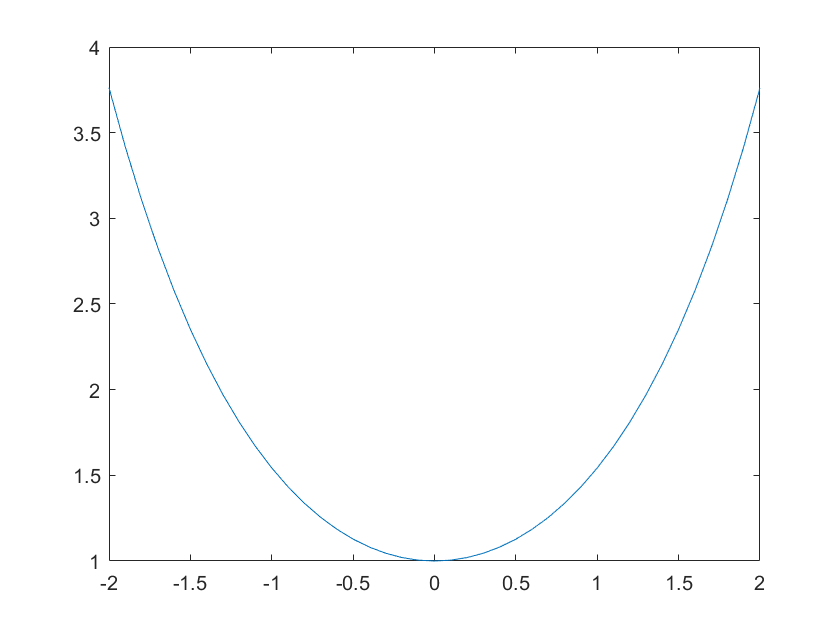

x=-2:0.1:2;
y=(exp(x)+exp(-x))/2;
plot(x,y);